clc, clear all, close all;
data1 = xlsread('foam_simbaby_facing_reader.csv'); %free-space with ground plane large

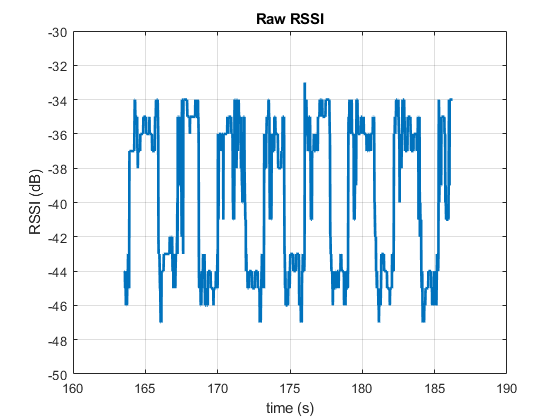

m=11000;
n=12483;
t1 = data1(m:n,3); %relative timestamp
r1 = data1(m:n,6); %RSSI dB
figure
plot(t1*1e-6,r1, 'LineWidth', 2);
grid on;
ylim([-50,-30]);
xlabel('time (s)'), ylabel('RSSI (dB)');
title('Raw RSSI');

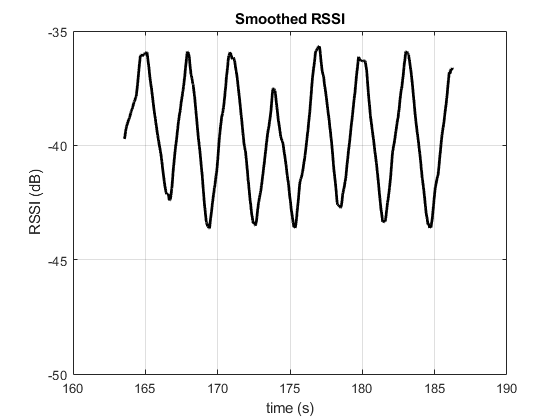


s = linspace(1,1,numel(t1));

figure
mm=100;
plot(t1*1e-6, movmean(r1,mm), 'LineWidth',2,'Color', 'black');
grid on;
title('Smoothed RSSI');
xlabel('time (s)'), ylabel('RSSI (dB)');
ylim([-50,-35]);

% grid minor;